# Frequency-Domain Stability · 학습

## 실행 조건

MATLAB · Control System Toolbox

## 이번에 배울 내용

Time Response를 모두 돌리기 전에, Frequency Response와 열린 고리의 Pole로 안정성을 판단해 봅니다.

## 전체 흐름

열린 고리 Pole → Nyquist 궤적 → 안정 여유 → Closed-loop Pole 확인

## Nyquist와 열린 고리의 Pole

−1 주위의 궤적만 세면 안정성을 잘못 판단할 수 있습니다. 열린 고리의 우반평면 Pole 수와 둘러싸는 방향의 부호를 함께 사용하고, 직접 계산한 Closed-loop Pole로 확인합니다.

## 안정 여유를 해석하는 조건

Gain Crossover Frequency는 Open-loop 응답의 크기가 1인 주파수입니다. 이 주파수의 Phase와 −180° 사이의 차이가 Phase Margin입니다.

Phase가 −180°인 주파수에서는 응답 크기의 역수가 Gain Margin입니다. Bode plot에 교차점을 표시하면 두 Margin이 어디서 계산되었는지 볼 수 있습니다.

## Frequency Response와 Closed-loop Pole 확인

L(s)=5/((s+1)(s+2)(s+3))의 Nyquist 궤적과 Closed-loop Pole을 확인합니다. 이 예는 열린 고리에 우반평면 Pole이 없습니다.

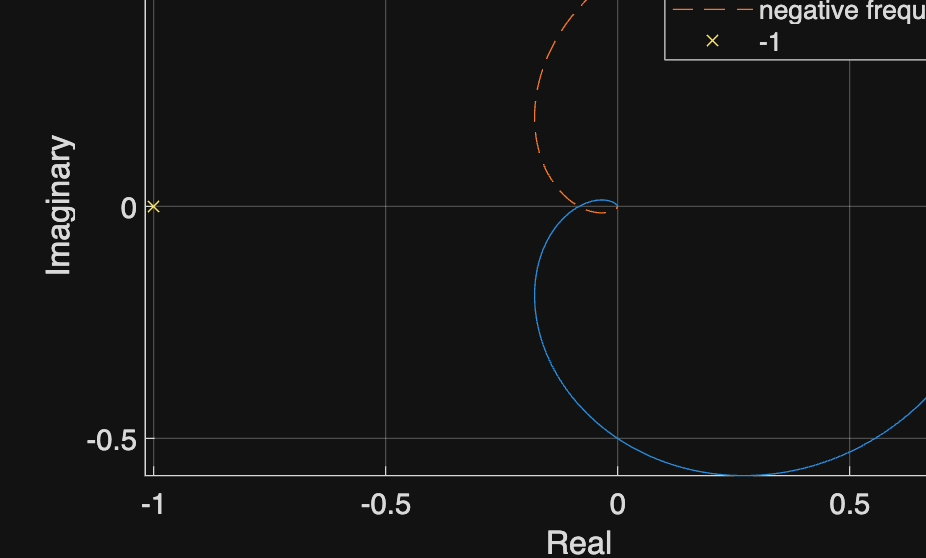

  -3.9042 + 0.0000i
  -1.0479 + 1.3112i
  -1.0479 - 1.3112i



%% Worked example
s=tf('s'); L=5/((s+1)*(s+2)*(s+3)); omega=logspace(-3,3,1000);
z=squeeze(freqresp(L,omega)); figure;
plot(real(z),imag(z),real(z),-imag(z),'--'); hold on; plot(-1,0,'x');
xlabel('Real'); ylabel('Imaginary'); axis equal; grid on
legend('positive frequency','negative frequency','-1'); disp(pole(feedback(L,1)));

## 참고 예제

추가 예제 보기

[참고 자료](https://chorok-daddy.github.io/niil/courses/control-2/frequency-stability/index.html)